We look at the balance between the axial spring and the magnet to lock the claw in position axially

clear
clf
format short

considering a constant spring constant we get the pull of one **axial spring** from SODEMANN

% k_axial = 0.29e3; % N/mm --> N/m % max kraft 47,43, max vandring 140,97, total lenth 229,87
% % varenummer 	E07500633500S trækfjeder SODEMANN
% x_axial = 140e-3; % udspændt fjeder til træk af claw

% k_axial = 0.65e3; % N/mm --> N/m % max kraft 56,94, max vandring 77,72, total lenth 141,22 L0 = 63,50
% E07500632500M	 % varenummer trækfjeder SODEMANN
% x_axial = 70e-3; % udspændt fjeder til træk af claw

k_axial = 1.77e3; % N/mm --> N/m % max kraft 137,09, max vandring 70,36, total lenth 159,26 L0 = 	88,90
% E07500853500M % varenummer trækfjeder SODEMANN
x_axial = 65e-3; % udspændt fjeder til træk af claw

F_spring_axial = k_axial * x_axial

F_spring_axial = 115.0500

Frication acting on the calw is devided in to two kinds that are added up.

- Due to gravity we find

g = 9.82;
m_claw = 14.8; %kg <--------- differ between claws
f_s = 0.20; %static / kinetic friction coeffecient %steel on steel
F_claw_fric = g * m_claw * f_s

F_claw_fric = 29.0672

We sum the forces and add them

syms F_n_x
F_n_x_eq = 0 == F_spring_axial - F_claw_fric + F_n_x;

F_n_x_sol = solve(F_n_x_eq, F_n_x);
F_n_x_sol = double(F_n_x_sol)

F_n_x_sol = -85.9828

## plot

% syms F_n_x
% x_slut = 1e-3;
% xs = x_contact:2e-5:x_slut; %Distance between magnets
% for i = 1:length(xs)  
% 
%     x_axial = 140e-3 - xs(i); % udspændt fjeder til træk af claw
%     F_spring_axial = k_axial * x_axial;
% 
%     F_n_x_eq = 0 == F_spring_axial - F_magnet - F_claw_fric + F_n_x;
%     F_n_x_sol = solve(F_n_x_eq, F_n_x);
% 
%     F_n_x_sols(i) = double(F_n_x_sol);
%     F_magnets(i) = F_magnet; % for later use
% end
% 
% plot(xs*1000, F_n_x_sols, DisplayName="force needed to unlock")
% hold on
% 
% xline(x_contact*1000,'r--', DisplayName="start location of magnet")
% yline(0,'--', DisplayName="Release happens below")
% xlabel("Distance between magnets - $x [mm]$", Interpreter="latex")
% ylabel("Force requred to release - F_{n,x}[N]")
% grid("minor")
% legend(location='best')
% hold off

**Release force**

n_stack = 2; %number of stacked disc springs for more force
F_realese = 553 * n_stack; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s = 0.53e-3;
s = 2.5

s = 2.5000

k = 7.59

k = 7.5900

% tallerken fjeder vare nummer 1800-620-70


% Tryk fjeder C04200350500S

r = 0.092/2 - 0.012

r = 0.0340

T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring

T_to_store = 75.2080

F_to_store = 2 / r % how much torque i needed to store energi in the spring

F_to_store = 58.8235


% F_realese = 2*45;% for testing
F_realese = 2*k*s% for testing

F_realese = 37.9500


% T = F_realese * r
W = 100/r * s ;% F_realese * s % The work the spring does on the rotor
W = F_realese * s/1000 % F_realese * s % The work the spring does on the rotor

W = 0.0949


syms omega
I = 0.0012; %HMA4 80 1-2
% I = 0.0057;HMA4 90S-6
% I = 0.1617; %HMA4 160L-6
% I = 0.335; % HMC4 225M-2
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-2
% I = 15.9356; % inertia of the test motor % HMC4 355L-2 <--------- differ from motor to motor
W_eq = W == 1/2 * I * omega^2; % work of the rotor
omega_sol = solve(W_eq, omega);
omega = double(omega_sol(2))

omega = 12.5748

Dermed har jeg hastigheden ved slip, kraften aftager løbende i fjederen men antage at være tæt på F_realease_x i det kontakten slippes.

Couplings delen skal rejse 1 mm og tabet her negligeres

F_fric = F_spring_axial * f_s /4

F_fric = 5.7525



double(omega_sol(2))

ans = 12.5748

r_outer = 0.092/2 - 0.012 %0.066;

r_outer = 0.0340


phi_tab = 8; % arc of tab
s_fric = 2*pi*r_outer * phi_tab/360

s_fric = 0.0047

W_fric = F_fric * s_fric

W_fric = 0.0273


energi_left = W - W_fric

energi_left = 0.0676

% rad2deg(8)
deg2rad(8)

ans = 0.1396

syms omega
W_eq = 1/2 * I * omega^2 ==  W - W_fric;
sol = solve(W_eq,omega);
sol_omega = double(sol(2))

sol_omega = 10.6118


t = 1; %sek
s = sol_omega*r_outer*t

s = 0.3608

Torque area - Falde tryk


% A = 1593 * 2; %mm^2
r_outer = [0.066 0.046 0.035]

r_outer =     0.0660    0.0460    0.0350


A = 574 * 2; %mm^2
T = [10e3 1e3 0.1e3];
S = T/r_outer / A

S = 80.2951


n_y = 2; %Sikkerheds factor
S_y = 375; %375 - 460 % edu pack C45 - AISI 1040
S_max =  S_y / n_y

S_max = 187.5000

syms A_sym

A_min_eq = S_max == T(1)/r_outer(1) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol = 404.0404

A_min_eq = S_max == T(2)/r_outer(2) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol = 57.9710

A_min_eq = S_max == T(3)/r_outer(3) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol = 7.6190


% for i = length(T)
%     A_min_eq = S_max == T(i)/(r_outer(i) * A_sym*2);
%     A_min_sol = solve(A_min_eq, A_sym);
%     A_min(i) = double(A_min_sol);
% end
% A_min

Aksel for dimentionering

 ved flydnign

T_max = [10e3 10e3 1e3 0.1e3]; %Nm
% d = 95e-3; %mm
n_y = 2; %drev Kraftige stød % arbejds maskinen Lette stød
S_y = 375; %375 - 460 % edu pack C45 - AISI 1040

% tau_max_Pa = T_max / (pi/16 * d^3) 
% ta_max_MPa = tau_max_Pa/1e6
tau_til = 1/sqrt(3) * S_y / n_y

tau_til = 108.2532


d_m = (T_max / (pi/16  * tau_til * 1e6)).^(1/3)

d_m =     0.0778    0.0778    0.0361    0.0168


d_mm = d_m * 1000

d_mm =    77.7756   77.7756   36.1002   16.7562


for hollow shaft

d = [88e-3 42e-3 30e-3 20e-3]; % inner diameter
D_sol = zeros(1, length(T_max));

    
% D_sol = double(solve(D_eq, D))

for i = 1:length(T_max)
    syms D
    W_p = pi * (D^4 - d(i)^4)/(16*D);
    D_eq = tau_til*1e6 == T_max(i) / W_p;
    
    D_sol = solve(D_eq, D);
    D_sols(i) = double(D_sol(4));
end

D_sols

D_sols =     0.1019    0.0799    0.0406    0.0227


D_sols_mm = D_sols *1e3

D_sols_mm =   101.9241   79.8659   40.6136   22.7302


Tightning force

format shortg
F_pre = [58.57e3 13.866e3 4.357e3] * 2 %N % pretension on two bolts

F_pre =       117140       27732        8714


% M20 M10 M6
d_shaft = 95e-3;
T_max = [10e3 1e3 0.1e3];
F_max = T_max ./ d_shaft

F_max =    1.0526e+05        10526       1052.6


Spline

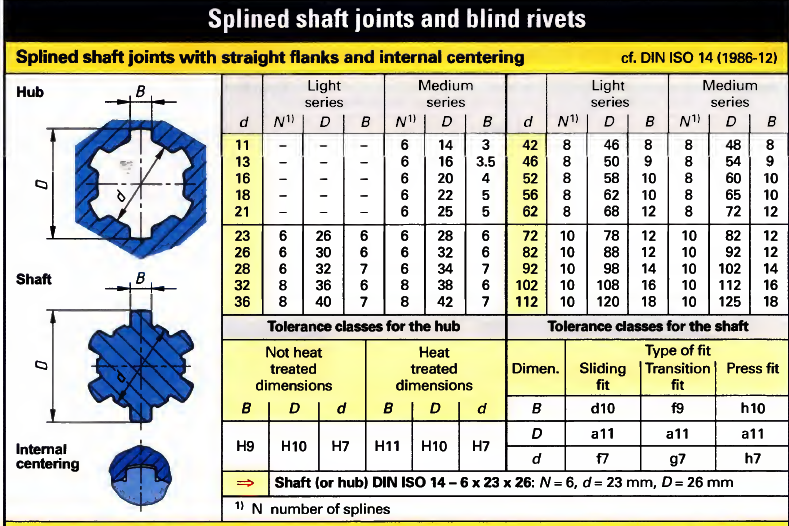

T_max = [10e3 1e3];
d = [82e-3 42e-3]; % d>77,8 see above %shaft diameter
N = [10 8]; %number of theeth
% D = 92e-3; %medium series outer diameter
D = [88e-3 46e-3]; %light series outer diameter
B = [12 8]; %width of tooth

L = [75e-3 75e-3];%length of spline interacion
r = (D./2 - (D-d)./2)

r =         0.041        0.021


F = T_max ./ r

F =     2.439e+05        47619


A = (D-d)./2 .* L %areal i kontakt pr spline

A =      0.000225      0.00015


S_Pa = F ./ (A .* N)

S_Pa =     1.084e+08   3.9683e+07


S_MPA =S_Pa /1e6

S_MPA =         108.4       39.683


Spline holds on Light series

DIN 5480-16 2006

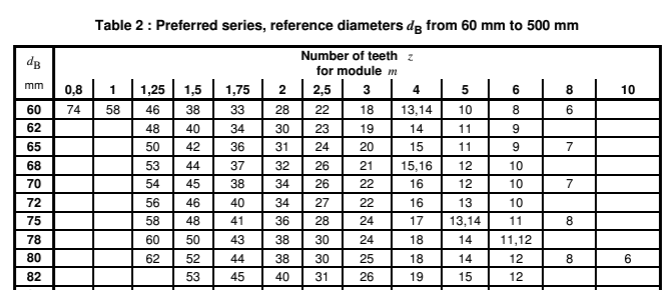

% d_B

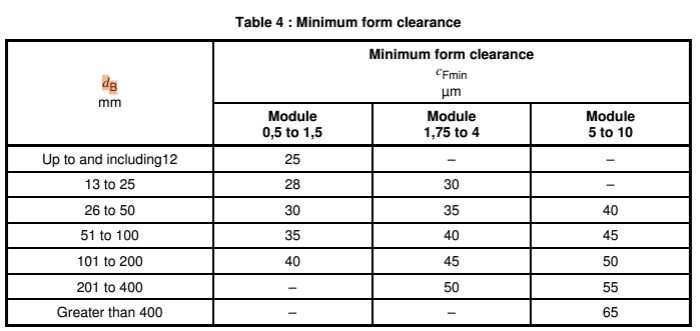

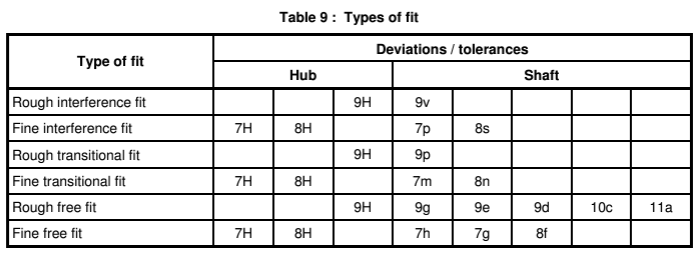

shaft 9e

hub 9H

se side 103 i den blå

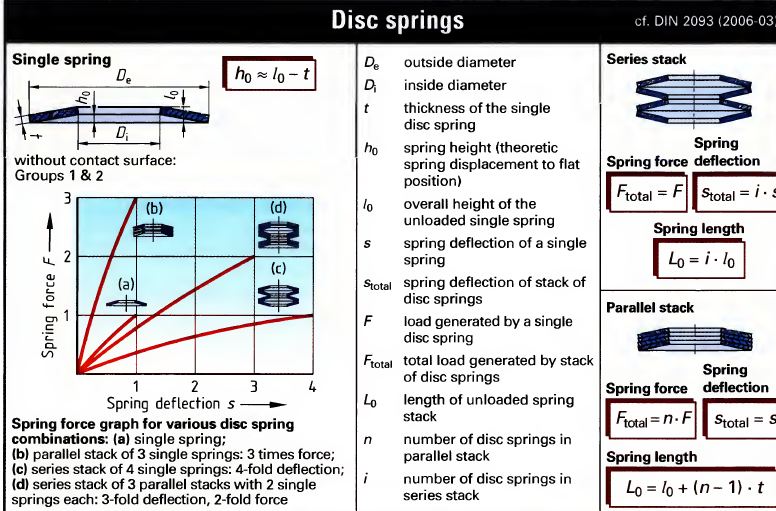

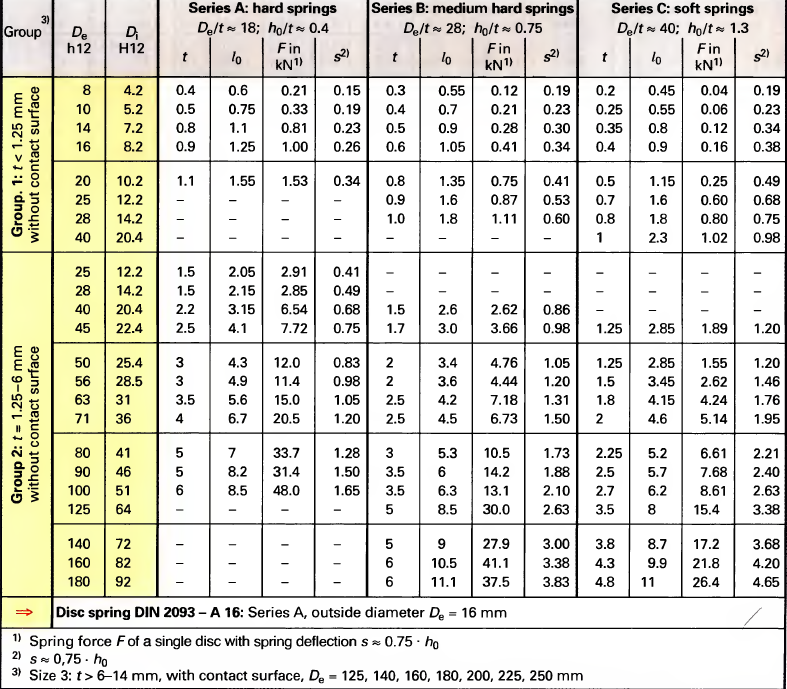

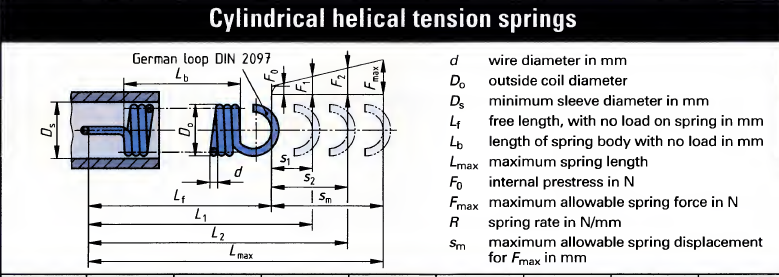

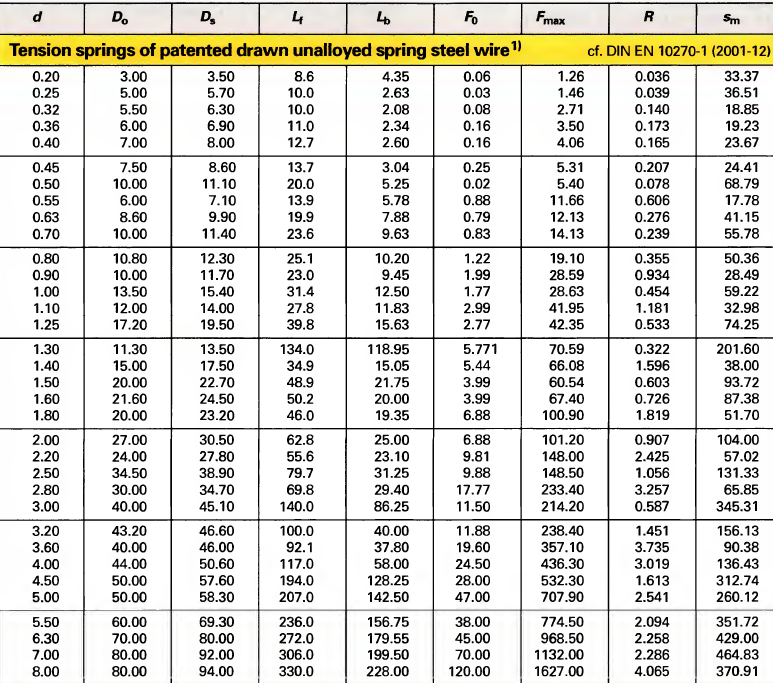

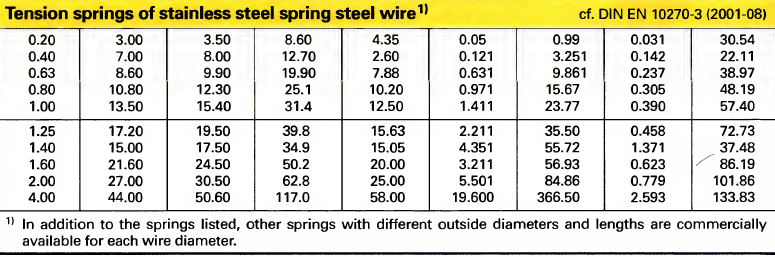

## Spring energi calculations

100 Nm tranducer

**Motor**

clear
clf
r = 0.035 - 0.012 % fixed radius % radius where the force is apllied

r = 0.0230

%this is also the approximate middle point of the friction

% I = 0.0012; %HMA4 80 1-2
% I = 0.0057;HMA4 90S-6
% I = 0.1617; %HMA4 160L-6
I = 0.335; % HMC4 225M-2 % possible for 120hz 

%compression of spring if not fully
% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring
% T = 1.2 % minimum torque for 120 Hz 2 pole FS 71, 0.7 for non overload
T = 96 % HMC4 225M-2 at 120 Hz 

T = 96

F_to_store = T / r % how much torque i needed to store energi in the spring

F_to_store = 4.1739e+03

**Radial spring data**

% C07200630620S % 	fri længde=	15,75 max vandring = 6,96 De=18,29 Di =15,09
s_spring_max = 2e-3 % Max compression if depends on allowed clearance (measure) 

s_spring_max = 0.0020

k_spring = 9.11e3%7.59e3 % spring constant

k_spring = 9110


% T / r = k_spring * s_spring_max
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

s_spring_push = 0.2291


if s_spring_max > s_spring_push
    s_spring_max = s_spring_push
else
    s_spring_max
end

s_spring_max = 0.0020

F_spring = k_spring * s_spring_max * 2

F_spring = 36.4400

**Axial spring**

f_k = 0.2; %kinetic friction coeffecient for steel vs steel
k_axial = 0.57e3; % N/mm --> N/m % max kraft 41,87, max vandring 66,80, total lenth 123,95 L0 = 57,15
% E08500632250S % varenummer trækfjeder SODEMANN
x_axial = 55e-3; % udspændt fjeder til træk af claw
F_axial = k_axial * x_axial

F_axial = 31.3500

F_fric = F_axial * f_k

F_fric = 6.2700

**Energi**

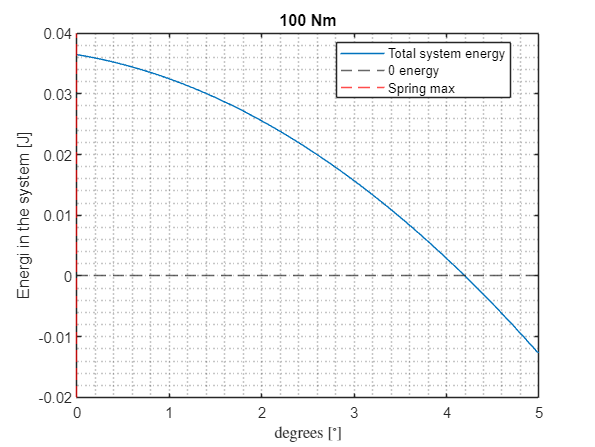

thetas = 0:0.01:5; % angle traveld

syms omega
for i = 1:length(thetas)
    % thetas(i) %degree we calculate

    x = 2*pi*r * thetas(i)/360; % travel on the circle

    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations 
        % spring push distance
    else
        s_spring = s_spring_max;
    end
    
    % W_spring = 1/2 * k_spring * s_spring^2 * 2; % two springs
    W_spring = k_spring * (s_spring_max^2 - s_spring^2); % two springs
    if W_spring > 0
        % W_spring
    else
        W_spring = 0;
    end
    W_fric = F_axial * f_k * x;
    W_total(i) = W_spring - W_fric; 

    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total);
theta_spring_max = thetas(max_index); % holder for max spring

plot(thetas, W_total, DisplayName="Total system energy")
hold on
yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("100 Nm")
hold off



[max_value2, max_index2] = max(real(omega_sol2));
theta_max_speed = thetas(max_index2); % holder for max spring

plot(thetas, omega_sol2, DisplayName="Angluar speed")

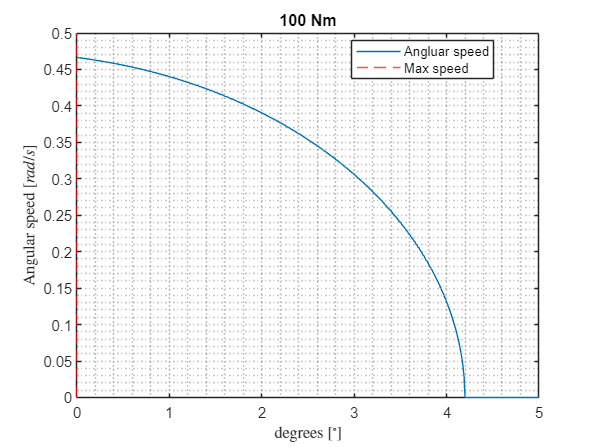

hold on
xline(theta_max_speed, 'r--', DisplayName='Max speed')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("100 Nm")
hold off

x = 2*pi*r * 0.1/360

x = 4.0143e-05

1 kNm tranducer

**Motor data**

clear
clf
r = 0.092/2 - 0.012 % fixed radius % radius where the force is apllied

r = 0.0340

%this is also the approximate middle point of the friction

I =  0.0095; % HMA4 112M-2
% I = 0.1617; %HMA4 160L-6
% I = 0.335; % HMC4 225M-2
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 5.7105; % HMC4 315L2-6

%compression of spring if not fully
% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring
T = 102 % minimum torque for 10 Hz 2 pole FS 112

T = 102

% T = 934 % minimum torque for 120 Hz 6 pole FS 315 (HMC4 315L2-6)
F_to_store = T / r % how much torque i needed to store energi in the spring

F_to_store = 3000

**Radial spring data**

n_stack_para = 1; %number of paralel stacked disc springs for more force
n_stack_series = 1; %number of series stacked disc springs for more force
F_realese = 553 * n_stack_para; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s_spring_max = 0.5e-3 * n_stack_series; %(0.53e-3)
k_spring = F_realese / s_spring_max

k_spring = 1106000



% T / r = k_spring * s_spring_max
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

s_spring_push = 0.0014


if s_spring_max > s_spring_push
    s_spring_max = s_spring_push
else
    s_spring_max
end

s_spring_max = 5.0000e-04

F_spring = k_spring * s_spring_max * 2

F_spring = 1106

Axial spring

k_axial = 1.77e3; % N/mm --> N/m % max kraft 137,09, max vandring 70,36, total lenth 159,26 L0 = 	88,90
% E07500853500M % varenummer trækfjeder SODEMANN
x_axial = 65e-3; % udspændt fjeder til træk af claw
F_axial = k_axial * x_axial

F_axial = 115.0500

Energi

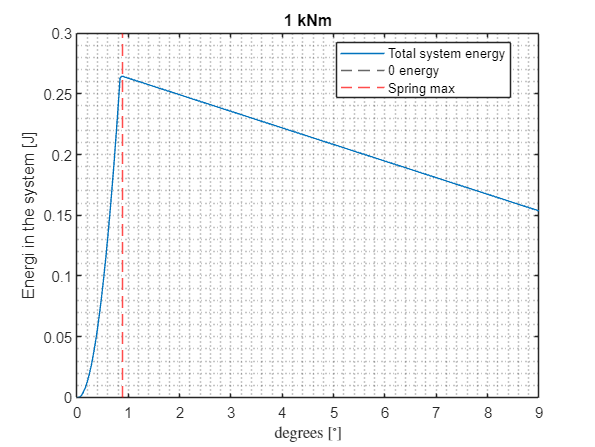

f_k = 0.2; %kinetic friction coeffecient for steel vs steel
thetas = 0:0.04:9; % angle traveld

syms omega
for i = 1:length(thetas)
    % thetas(i) %degree we calculate

    x = 2*pi*r * thetas(i)/360; % travel on the circle

    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations % spring
    else
        thetas(i);
        s_spring = s_spring_max;
    end
    
    W_spring = 1/2 * k_spring * s_spring^2 * 2; % two springs
    W_fric = F_axial * f_k * x;
    W_total(i) = W_spring - W_fric; 

    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total);
theta_spring_max = thetas(max_index); % holder for max spring

plot(thetas, W_total, DisplayName="Total system energy")
hold on
yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("1 kNm")
hold off

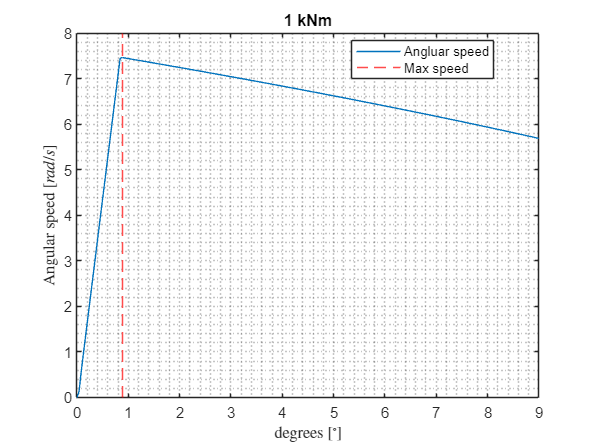



[max_value2, max_index2] = max(real(omega_sol2));
theta_max_speed = thetas(max_index2); % holder for max spring

plot(thetas, omega_sol2, DisplayName="Angluar speed")
hold on
xline(theta_max_speed, 'r--', DisplayName='Max speed')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("1 kNm")
hold off

10 kNm tranducer

Radial spring data

clear
clf
r = 0.092/2 - 0.012 % fixed radius % radius where the force is apllied
%this is also the approximate middle point of the friction


s_spring_max = 4e-3 % Max compression if depends on allowed clearance (measure) 
k_spring = 7.59e3 % spring constant

% n_stack = 2; %number of stacked disc springs for more force
% F_realese = 553 * n_stack; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
% s_spring_max = 0.53e-3;
% k_spring = F_realese / s_spring_max

%compression of spring if not fully
% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring
% T = 1.2 % minimum torque for 120 Hz 2 pole FS 71, 0.7 for non overload
T = 96 % HMC4 225M-2 at 120 Hz 
F_to_store = T / r % how much torque i needed to store energi in the spring

% T / r = k_spring * s_spring_max
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

if s_spring_max > s_spring_push
    s_spring_max = s_spring_push
else
    s_spring_max
end
F_spring = k_spring * s_spring_max * 2

Axial spring

k_axial = 1.77e3; % N/mm --> N/m % max kraft 137,09, max vandring 70,36, total lenth 159,26 L0 = 	88,90
% E07500853500M % varenummer trækfjeder SODEMANN
x_axial = 65e-3; % udspændt fjeder til træk af claw
F_axial = k_axial * x_axial / 4

Energi

f_k = 0.2; %kinetic friction coeffecient for steel vs steel
thetas = 0:0.1:11; % angle traveld
I = 0.0012; %HMA4 80 1-2
% I = 0.0057;HMA4 90S-6
% I = 0.1617; %HMA4 160L-6
% I = 0.335; % HMC4 225M-2
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-2
% I = 15.9356; % inertia of the test motor % HMC4 355L-2
syms omega
for i = 1:length(thetas)
    % thetas(i) %degree we calculate

    x = 2*pi*r * thetas(i)/360; % travel on the circle

    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations % spring
    else
        thetas(i);
        s_spring = s_spring_max;
    end
    
    W_spring = 1/2 * k_spring * s_spring^2 * 2; % two springs
    W_fric = F_axial * f_k * x;
    W_total(i) = W_spring - W_fric; 

    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total)
theta_spring_max = thetas(max_index) % holder for max spring

plot(thetas, W_total, DisplayName="Total system energy")
hold on
yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("10 kNm")
hold off


[max_value2, max_index2] = max(real(omega_sol2))
theta_max_speed = thetas(max_index2) % holder for max spring

plot(thetas, omega_sol2, DisplayName="Angluar speed")
hold on
xline(theta_max_speed, 'r--', DisplayName='Max speed')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("10 kNm")
hold off